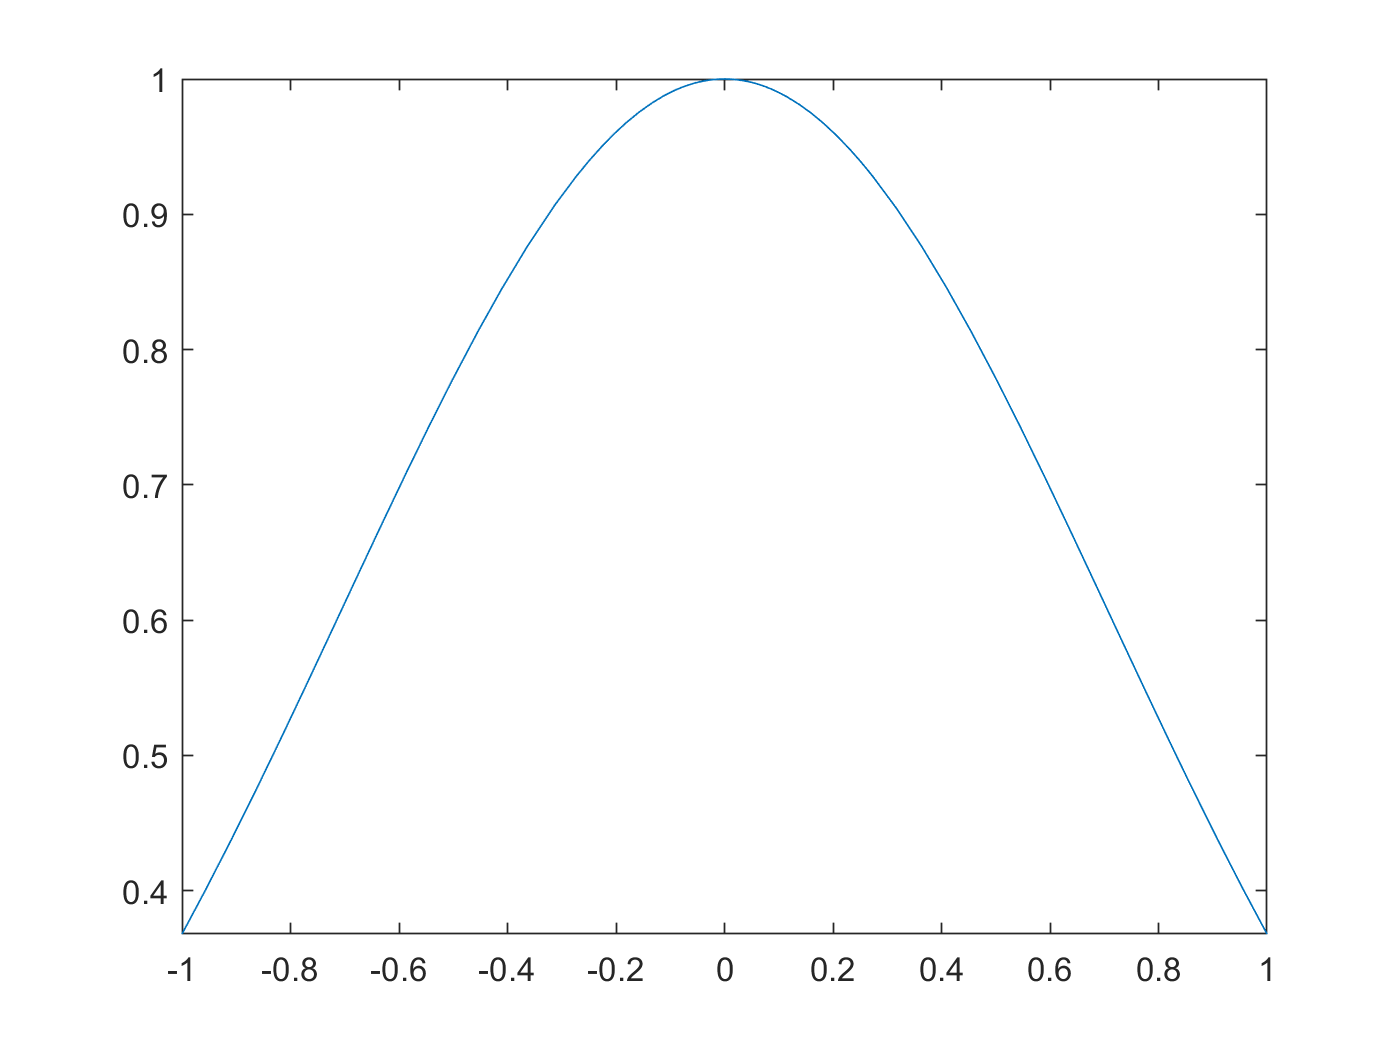


%values of coefficients and polynomial defined
a=1;
b=2;
c=3;
syms y(x);
y(x)=exp(-x^2);
fplot(y,[-1 1])

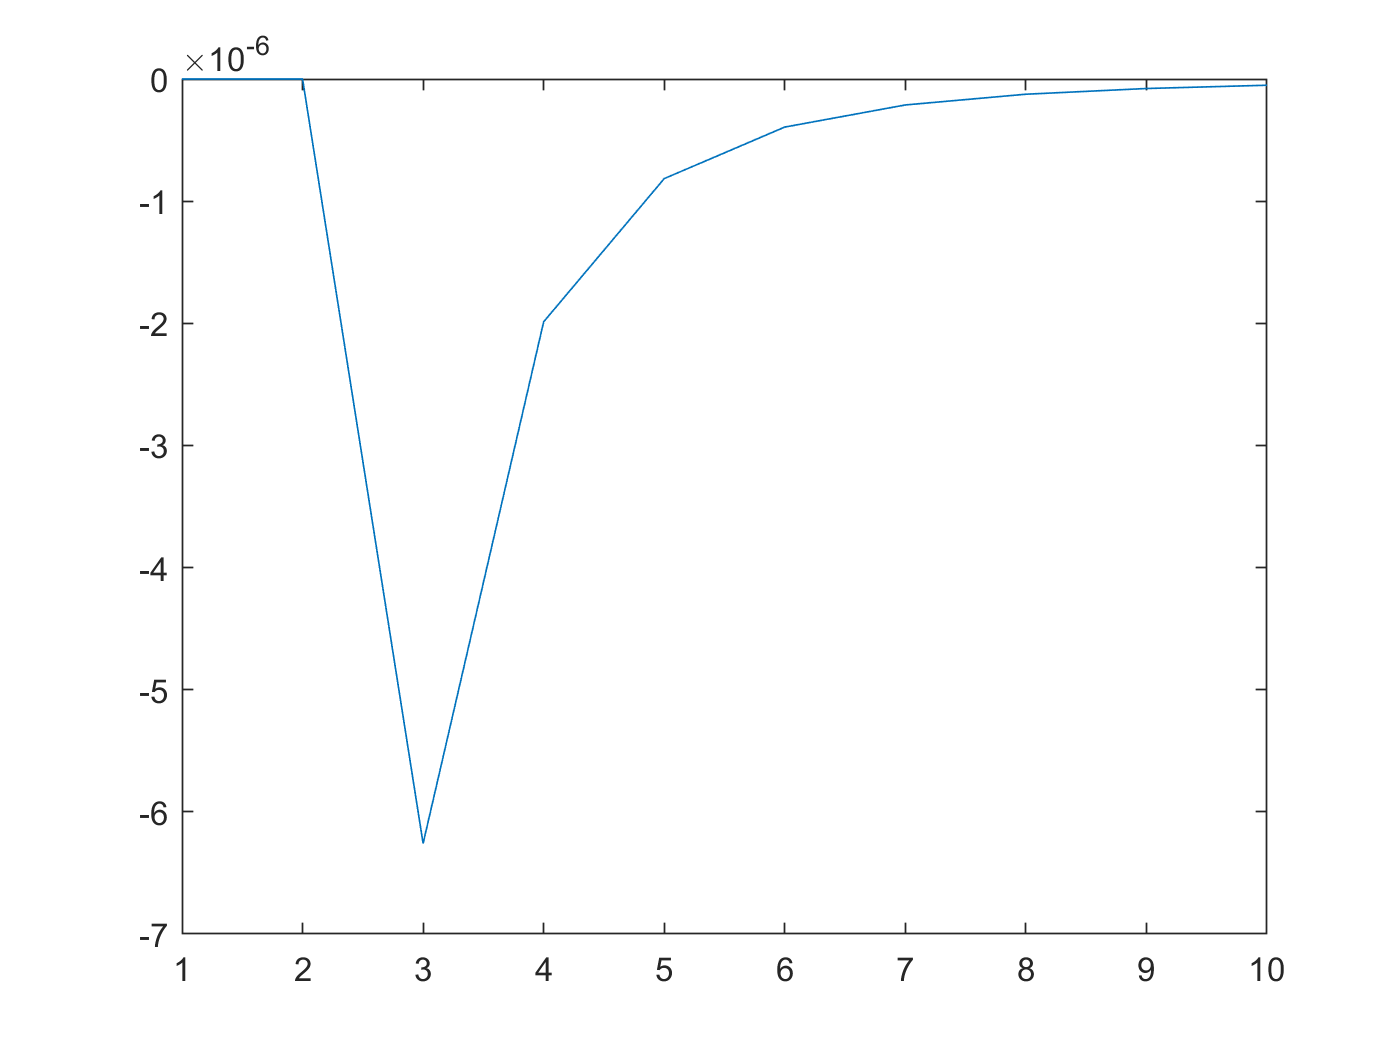

IntAna=int(y(x),0,1);   %analytical integration

%interval definitions
uppBound=1;

for NoInt=3:10
    x0=0;
    %calculate parameters
    h=(uppBound-x0)/(2*NoInt)  ;     %distance of intervals
    x1=x0+h;
    x2=x0+2*h;
    %initialise solution
    IntApprox=0;
    z=x0;
        for i=2:(NoInt+1)
     y0=exp(-x0^2);
     y1=exp(-x1^2);
     y2=exp(-x2^2);
     %add new term to approximation
     IntApprox=IntApprox+h*((1/3)*y0+(4/3)*y1+(1/3)*y2);
     %set new values to x0 x1 and x2
     x0=x2;
     x1=z+(2*i-1)*h;
     x2=z+2*i*h; 
     end
diff(NoInt)=IntAna-IntApprox;
end
plot(diff)

IntApprox

IntApprox = 0.7468